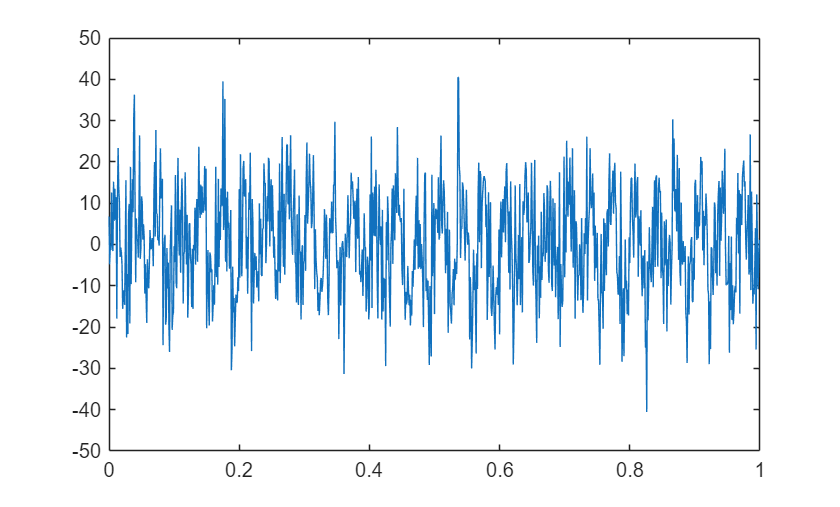

clear
sampling_rate = 1000; % hz
num_samples = 1000;
sampling_period = 1/sampling_rate; %s

signal_frequency = 30; %hz
signal_magnitude = 10;

t = (0:num_samples - 1).*sampling_period;
samples = signal_magnitude.*sin(2.*pi.*signal_frequency.*t);
noise = 10*randn(size(samples));
samples = samples + noise;

plot(t, samples)

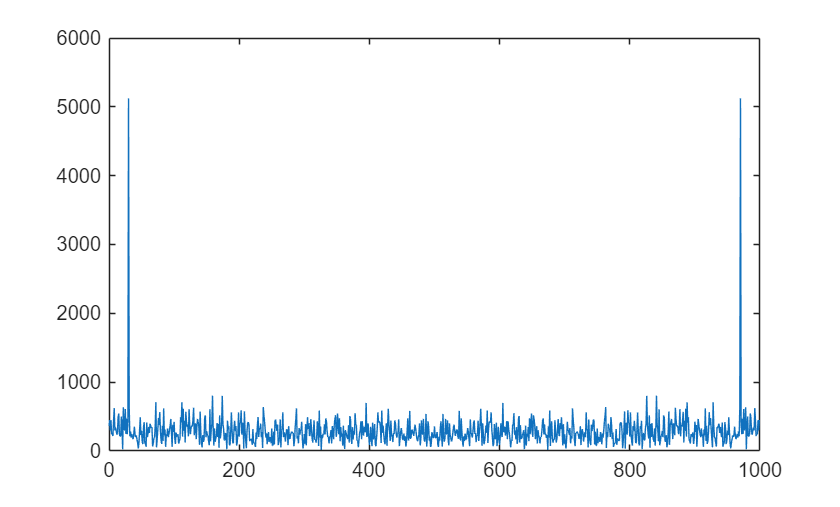

frequency_spectrum = fft(samples);
x = (sampling_rate/num_samples)*(0:num_samples-1);
y = abs(frequency_spectrum);

x = x(1:end);
y = y(1:end);
plot(x,y);